clc; clear all; close all; 

% Importing variable names
table = readtable('PRSA_Data_Aotizhongxin_20130301-20170228.csv');

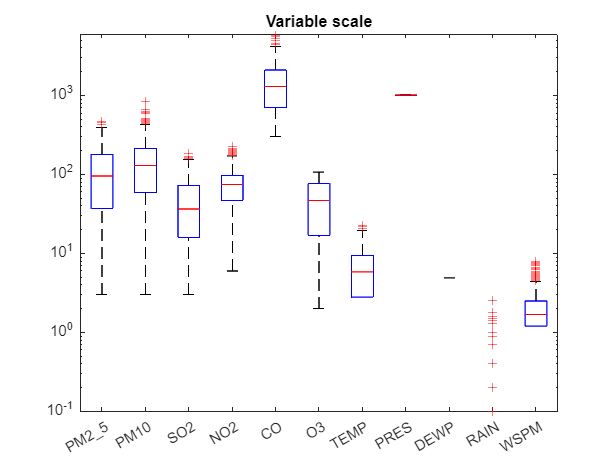


% Dropping timestamp-related values and categorical variables
A  = table{1:744,[6:15, 17]};

% Import Variable Names
varNames = table.Properties.VariableNames([6:15, 17]);

% Import variables for timestamp 
B = table{1:744,2:5}; % [year, month, day, hour]

% Tackling Missing Data
[row, col] = find(isnan(A)); 
urow       = unique(row);

% Checking consecutive values
% Series of missing values

b = 1; % NaN in a row
a = 1; % sequence of NaN numbers
i = 1;
set.objects(a) = b; % NaN in a row for sequence a
set.no(a) = a; % sequence no.
set.initv(a) = urow(i); % initial value
for i = 2:length(urow)
    if urow(i) == (urow(i-1)+1)
        b = b+1; set.objects(a) = b;
    else
        a = a+1; set.no(a) = a;
        b = 1; set.objects(a) = b;
        set.initv(a) = urow(i);
    end
end

% 3188 missing values -> 932 spots in the dataset with missing values
singleMV = histc(set.objects,1); % Number of single missing values: 654 to interpolate

a = 1;
for i = 1:length(set.objects)
    if set.objects(i) ~= 1
        set.remset(a) = set.no(i);
        set.remval(a) = set.objects(i);
        set.reminit(a) = set.initv(i);
        a = a + 1;
    end
end

[set.remset, idx] = sort(set.remset, 'descend');
set.remval        = set.remval(idx);
set.reminit       = set.reminit(idx);

% Removing periods with multiple consecutive missing values
for i = 1:length(set.remset)
    A((set.reminit(i)):((set.reminit(i)+set.remval(i))),:) = [];
    B((set.reminit(i)):((set.reminit(i)+set.remval(i))),:) = [];
end

% Interpolating missing values with only one missig value in-between
% measurements
A = fillmissing(A, 'linear');
% Dataset boxplot
figure();
boxplot(A, varNames);
ax = gca; ax.YAxis.Scale = "log";
title("Variable scale");

## Findind most correlated variable

correlation = corr(A,A);

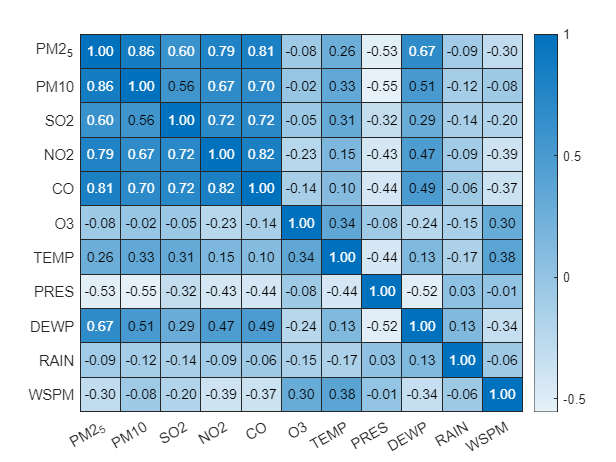


% Create heatmap with annotated correlation values
figure;
h = heatmap(varNames, varNames, correlation, 'ColorbarVisible', 'on');

% Annotate the heatmap with correlation values
h.CellLabelFormat = '%.2f'; 


j = 1;
for i = 1:11
    a = abs(correlation(:,i));
    sumVar(j) = sum(a);
    C(j) = i;
    j = j+1;
end
[val, idx] = max(sumVar)

val = 5.9808

idx = 1

## Model 1: (Group 3) Daily Seasonality

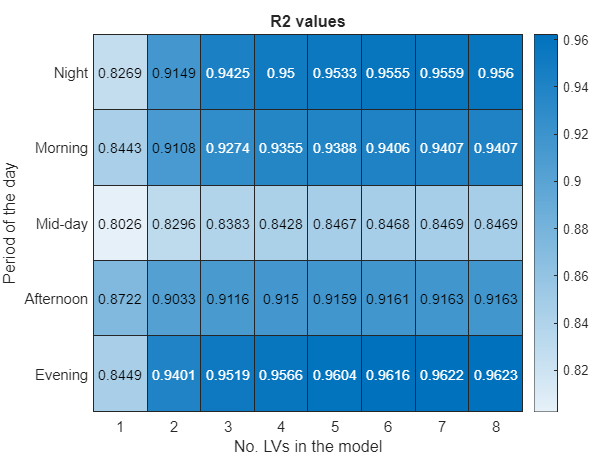

j = [0:5:23];
ncomp = 8;

for i = 1:5
    idxChunk    = intersect(find(B(:,4)>=j(i)),find(B(:,4)<(j(i)+5)));
    model(i).data = A(idxChunk,:);
    n           = length(model(i).data(:,1));
    

    % Calibration and test division
    division    = cvpartition(n, 'Holdout', 0.25);
    idxCal      = training(division);
    idxTest     = test(division);

    model(i).Xraw     = model(i).data(idxCal,   [1:idx-1, idx+1:end]);
    model(i).Xtestraw = model(i).data(idxTest,  [1:idx-1, idx+1:end]);
    model(i).Yraw     = model(i).data(idxCal,   idx);
    model(i).Ytestraw = model(i).data(idxTest,  idx);

    % Centering and scaling
    [model(i).X, model(i).mu, model(i).sigma] = zscore(model(i).Xraw);
    model(i).sigma(model(i).sigma == 0) = 0.000001;
    model(i).Xtest    = normalize(model(i).Xtestraw, 'Center', model(i).mu, 'scale', model(i).sigma);
    model(i).Y        = model(i).Yraw     - mean(model(i).Yraw);
    model(i).Ytest    = model(i).Ytestraw - mean(model(i).Yraw);

    for m = 1:ncomp
        [~, ~, ~, ~, model(i).ncomp(m).B, ~, ...
                model(i).ncomp(m).MSE, ...
                model(i).ncomp(m).stats] = plsregress(model(i).X, model(i).Y, m);
        
        % Calculate R2
        Yfit    = [ones(size(model(i).X,1),1) model(i).X] * model(i).ncomp(m).B;
        TSSRes  = sum((model(i).Y - mean(model(i).Y)).^2);
        RSSRes  = sum((model(i).Y - Yfit).^2);
        model(i).ncomp(m).R2 = 1 - RSSRes / TSSRes;
        
        % Calculate Q2
        YfitT   = [ones(size(model(i).Xtest,1),1) model(i).Xtest] * model(i).ncomp(m).B;
        PRESS = sum((model(i).Ytest - YfitT).^2);
        model(i).ncomp(m).Q2 = 1 - PRESS / TSSRes;
        
        % Storing for later 
        Beta(:,m) = model(i).ncomp(m).B;
    end
end

% Deciding on the number of components
R2 = [];
Q2 = [];

for m = 1:5
    for comp = 1:ncomp
        R2(m, comp) = model(m).ncomp(comp).R2;
        Q2(m, comp) = model(m).ncomp(comp).Q2;
    end
end

figure; 
yvalues = {"Night", "Morning", "Mid-day", "Afternoon", "Evening"};
xvalues = {'1', '2', '3', '4', '5', '6', '7', '8'};
heatmap(xvalues, yvalues, R2);
ylabel("Period of the day");
xlabel("No. LVs in the model");
title("R2 values");

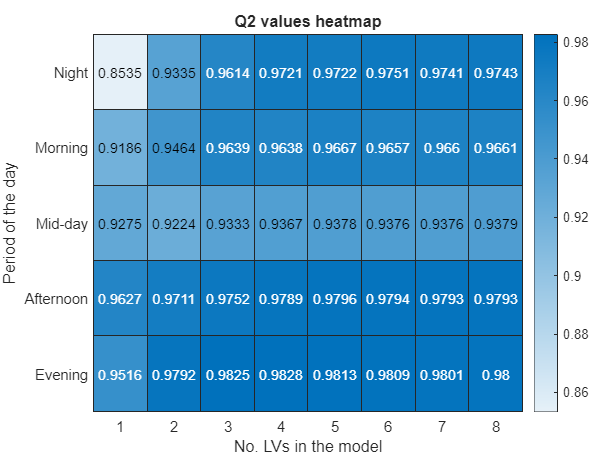


figure; 
yvalues = {"Night", "Morning", "Mid-day", "Afternoon", "Evening"};
xvalues = {'1', '2', '3', '4', '5', '6', '7', '8'};
heatmap(xvalues, yvalues, Q2);
ylabel("Period of the day");
xlabel("No. LVs in the model");
title("Q2 values heatmap");

 % Selectng model with three LVs


## Day-time seasonality (Group 3)

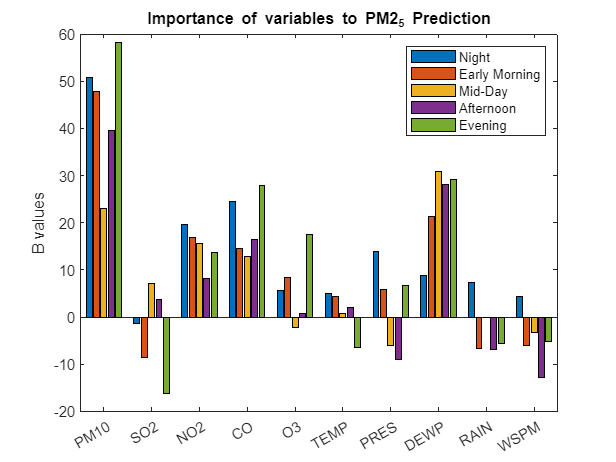



figure;
barMatrix = [];
for i = 1:5
    barMatrix = [barMatrix model(i).ncomp(3).B(2:end)];
end
bar(barMatrix);
xticklabels(varNames([1:idx-1, idx+1:end]));
ylabel("B values");
legend(["Night", "Early Morning", "Mid-Day", "Afternoon", "Evening"]);
title("Importance of variables to " + varNames(idx) + " Prediction");

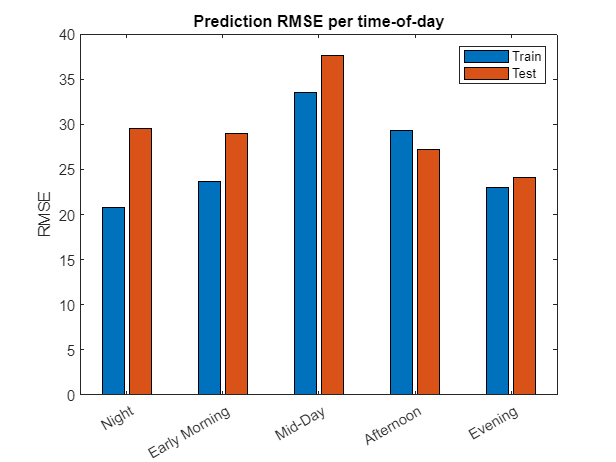


figure();
barMatrix = [];
for i = 1:5
    Yfit_train    = [ones(size(model(i).X,1),1) model(i).X] * model(i).ncomp(3).B;
    Yfit_test    = [ones(size(model(i).Xtest,1),1) model(i).Xtest] * model(i).ncomp(3).B;
    barMatrix = [barMatrix; rmse(Yfit_train, model(i).Y), rmse(Yfit_test, model(i).Ytest)];
end
bar(barMatrix);
% xticklabels(varNames([1:idx-1, idx+1:end]));
ylabel("RMSE");
xticklabels(["Night", "Early Morning", "Mid-Day", "Afternoon", "Evening"]);
legend("Train", "Test");
title("Prediction RMSE per time-of-day");

figure();

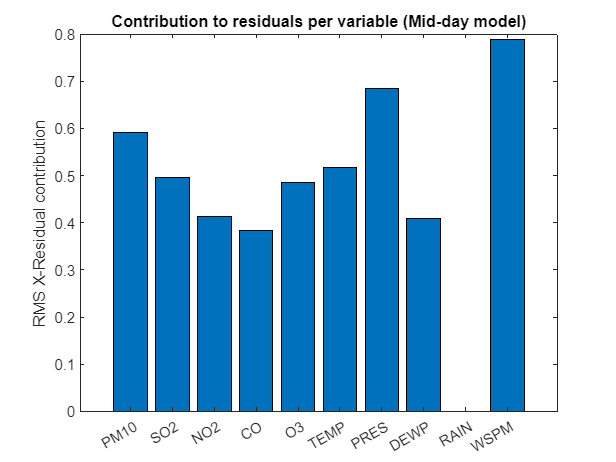

bar(sqrt(mean(model(3).ncomp(3).stats.Xresiduals.^2, 1)));
xticklabels(varNames([1:idx-1, idx+1:end]));
ylabel("RMS X-Residual contribution");
title("Contribution to residuals per variable (Mid-day model)");